% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc;
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 11;
avgNum = 15;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/LLAMPE Project/Preliminary Data/";
file_name = "Polystyrene_1_2024-05-07-10.40.30.583.csv";
file_path = strcat(data_path,file_name);
poly_may7 = readmatrix(file_path);

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/LLAMPE Project/Sample_Data_May_16_2024/2024-05-16/";
file_name = "Polystyrene_2024-05-15_80_100_2024-05-15-16.43.10.550.csv";
file_path = strcat(data_path,file_name);
poly_may15 = readmatrix(file_path);

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/LLAMPE Project/Sample_Data_May_16_2024/2024-05-16/";
file_name = "Polystyrene_2024-05-16_80_100_2024-05-16-10.39.41.927.csv";
file_path = strcat(data_path,file_name);
poly_may16 = readmatrix(file_path);

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/LLAMPE Project/Preliminary Data/";
file_name = "Silicon_2_2024-05-07-10.25.23.800.csv";
file_path = strcat(data_path,file_name);
silicon_may7 = readmatrix(file_path);

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/LLAMPE Project/Sample_Data_May_16_2024/2024-05-16/";
file_name = "Silicon_2024-05-15_34_100_2024-05-15-16.36.52.257.csv";
file_path = strcat(data_path,file_name);
silicon_may15 = readmatrix(file_path);

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/LLAMPE Project/Sample_Data_May_16_2024/2024-05-16/";
file_name = "Silicon_2024-05-16_34_100_2024-05-16-10.33.45.243.csv";
file_path = strcat(data_path,file_name);
silicon_may16 = readmatrix(file_path);

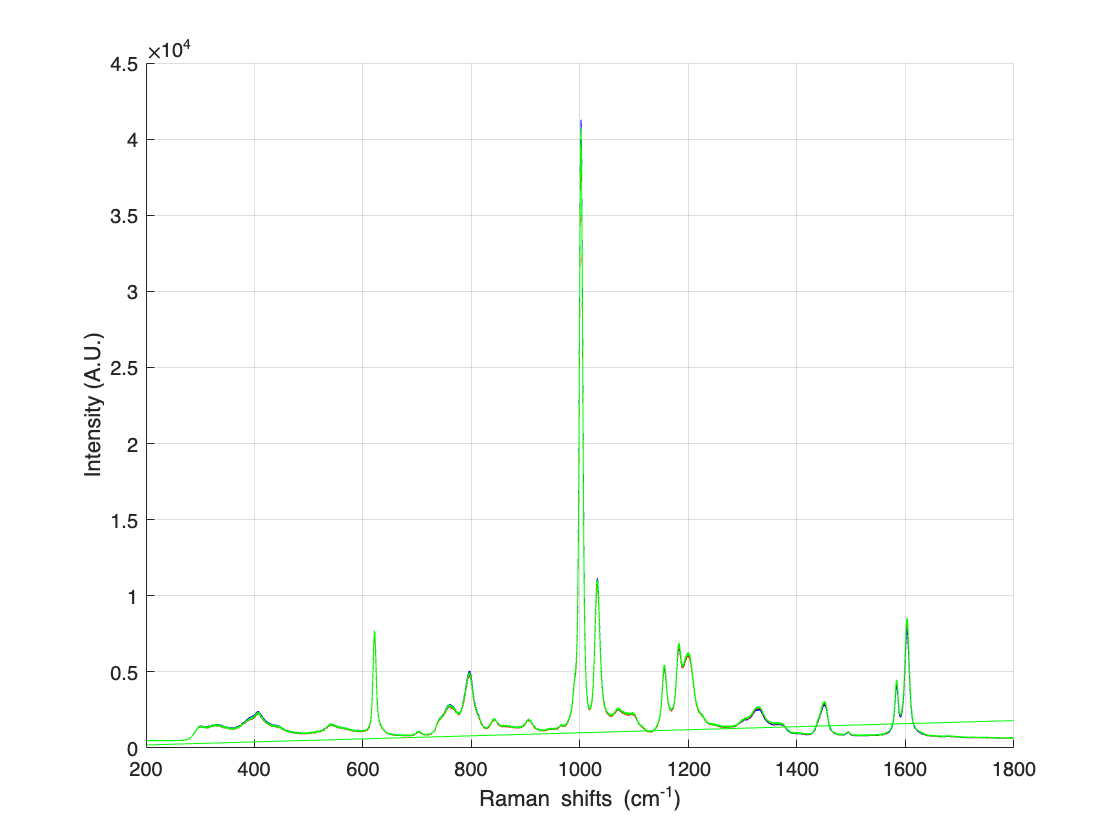

% Configuring and plotting unprocessed data

wavenumber = silicon_may16(1,:);
sil1 = silicon_may7;
sil2 = silicon_may15;
sil3 = silicon_may16;
poly1 = poly_may7;
poly2 = poly_may15;
poly3 = poly_may16;

% trimming standard sample data to these WN's
t1 = 200;
t2 = 1800;
wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];
sil1(:, sil1(1, :) <= t1) = [];
sil1(:, sil1(1, :) >= t2) = [];
sil2(:, sil2(1, :) <= t1) = [];
sil2(:, sil2(1, :) >= t2) = [];
sil3(:, sil3(1, :) <= t1) = [];
sil3(:, sil3(1, :) >= t2) = [];
poly1(:, poly1(1, :) <= t1) = [];
poly1(:, poly1(1, :) >= t2) = [];
poly2(:, poly2(1, :) <= t1) = [];
poly2(:, poly2(1, :) >= t2) = [];
poly3(:, poly3(1, :) <= t1) = [];
poly3(:, poly3(1, :) >= t2) = [];

% Plotting unprocessed data

figure;
hold on;
grid on;
plot(wavenumber, poly1, '-b');
plot(wavenumber, poly2, '-r');
plot(wavenumber, poly3, '-g');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
hold off;

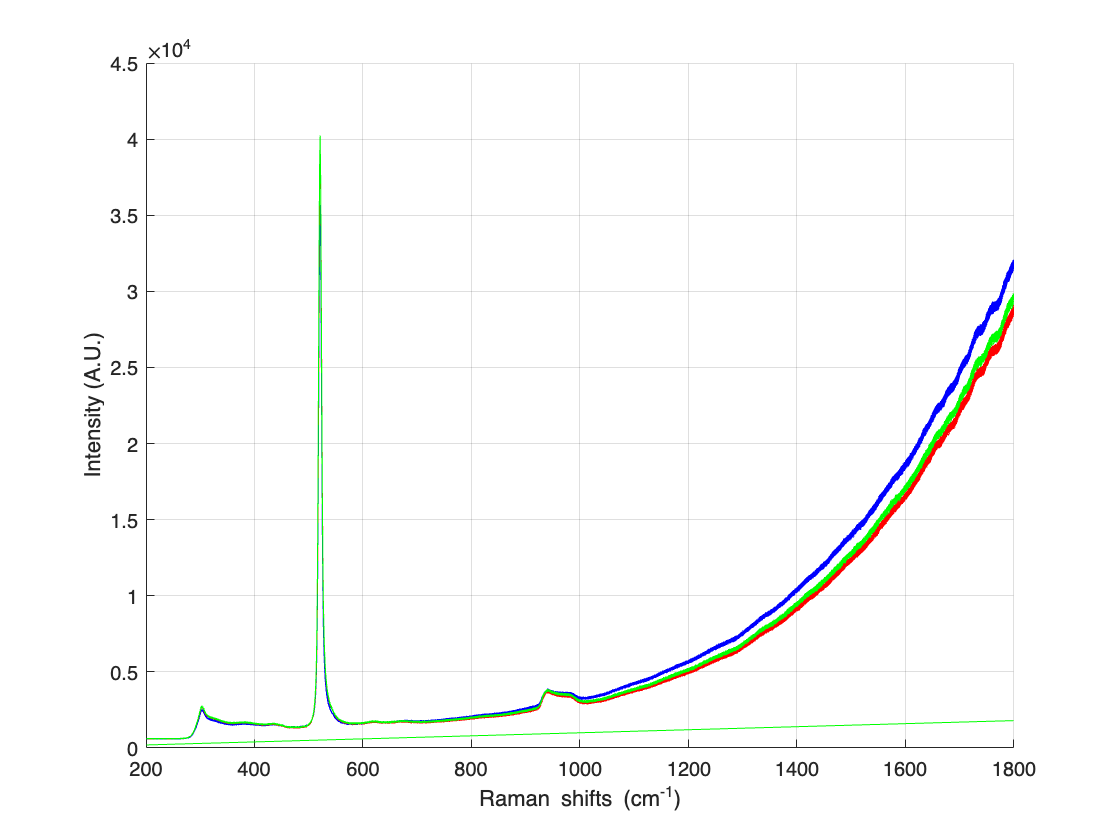


figure;
hold on;
grid on;
plot(wavenumber, sil1, '-b');
plot(wavenumber, sil2, '-r');
plot(wavenumber, sil3, '-g');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
hold off;

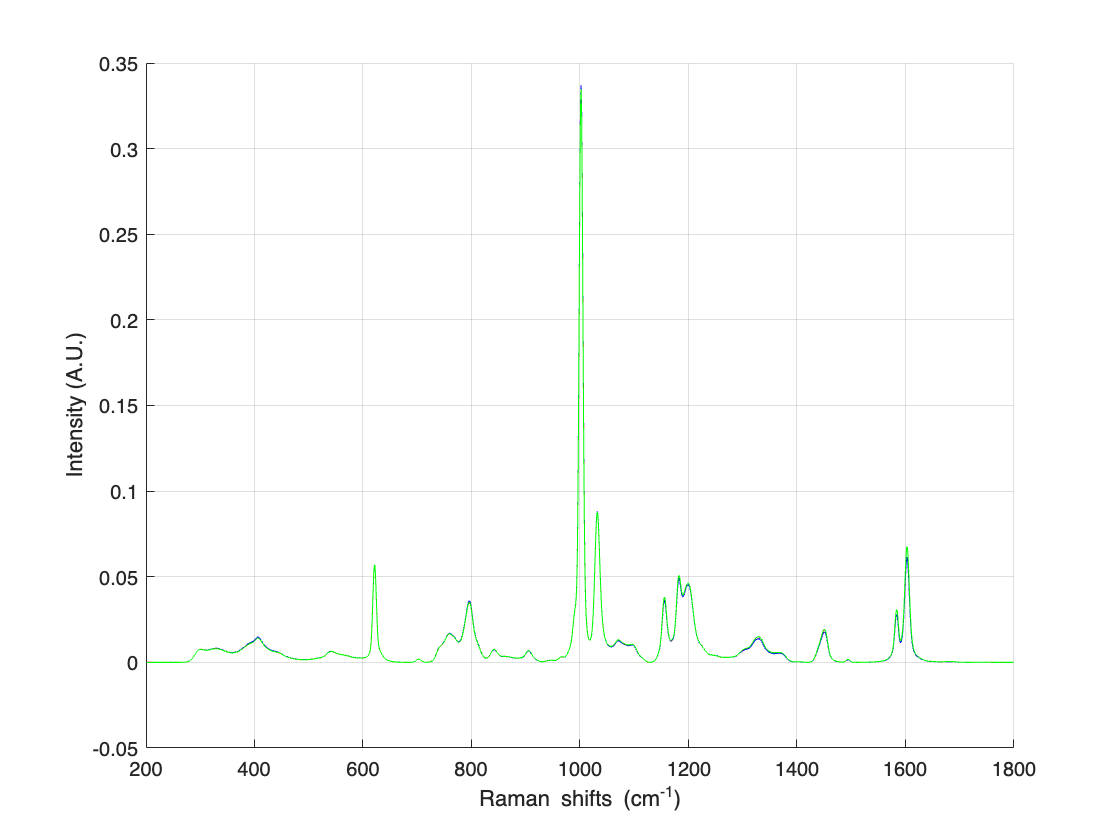

% Preprocessing the data

pro_sil1 = apply(sil1, [6,1,8,2,5,6,7]);
pro_sil2 = apply(sil2, [6,1,8,2,5,6,7]);
pro_sil3 = apply(sil3, [6,1,8,2,5,6,7]);

pro_poly1 = apply(poly1, [6,1,8,2,5,6,7]);
pro_poly2 = apply(poly2, [6,1,8,2,5,6,7]);
pro_poly3 = apply(poly3, [6,1,8,2,5,6,7]);

% Plotting pre-processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_poly1, '-b');
plot(wavenumber, pro_poly2, '-r');
plot(wavenumber, pro_poly3, '-g');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
hold off;

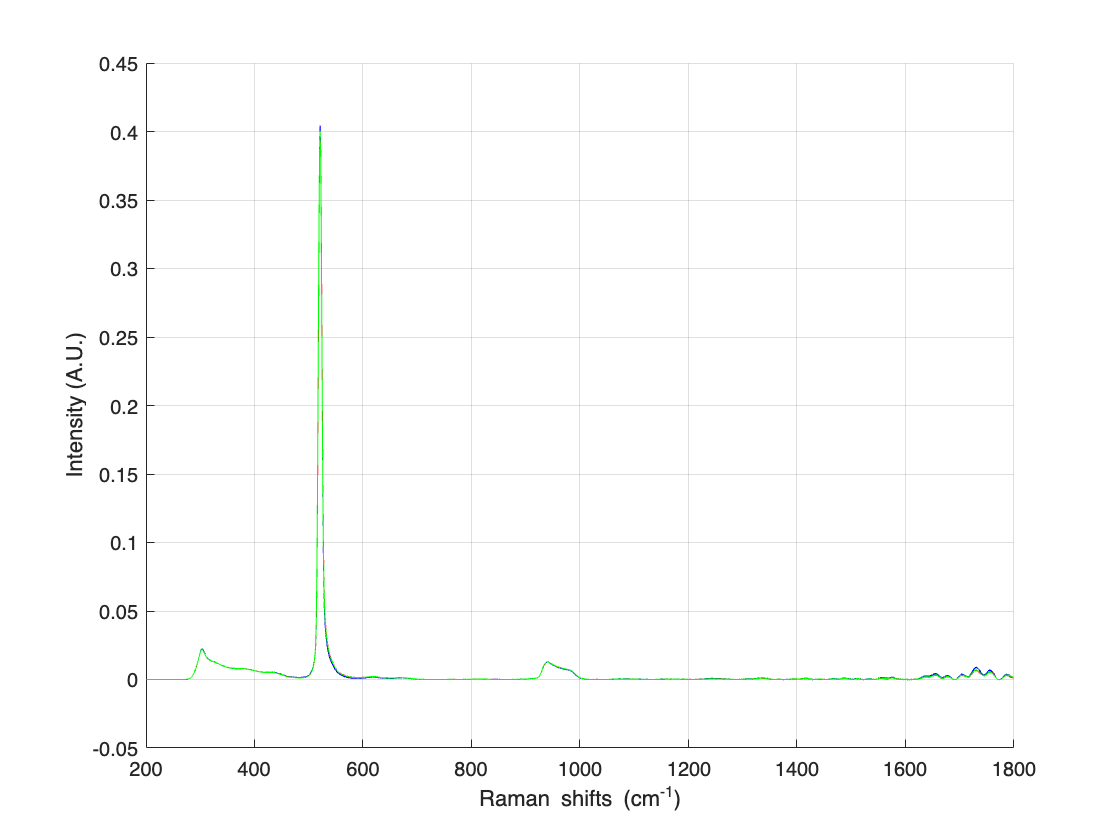


figure;
hold on;
grid on;
plot(wavenumber, pro_sil1, '-b');
plot(wavenumber, pro_sil2, '-r');
plot(wavenumber, pro_sil3, '-g');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
hold off;

% % ANOVA test for Polystyrene
% 
% % Reformat the intensity data into a single column
% intensities_poly = [pro_poly1(:); pro_poly2(:); pro_poly3(:)];
% 
% % Create a wavenumber label for each intensity reading
% wavenumbers = repmat(wavenumber(:), 6 * 3, 1);  % wavenumber repeated for each intensity reading
% 
% % Create a grouping variable for day
% days = [repmat({'May 7'}, numel(pro_poly1), 1); 
%         repmat({'May 15'}, numel(pro_poly2), 1); 
%         repmat({'May 16'}, numel(pro_poly3), 1)];
% 
% % Perform three-way ANOVA with wavenumbers and days as factors
% [p, tbl, stats] = anovan(intensities_poly, {wavenumbers, days}, 'model', 'interaction', 'varnames', {'Wavenumber', 'Day'});

% % ANOVA test for Silicon
% 
% % Reformat the intensity data into a single column
% intensities_sil = [pro_sil1(:); pro_sil2(:); pro_sil3(:)];
% 
% % Perform three-way ANOVA with wavenumbers and days as factors
% [p, tbl, stats] = anovan(intensities_sil, {wavenumbers, days}, 'model', 'interaction', 'varnames', {'Wavenumber', 'Day'});

% figure; % Create a new figure for the box plot
% boxplot(intensities_poly, days);
% xlabel('Day');
% ylabel('Intensity');
% title('Box Plot of Intensity Data Over Three Days for Polystyrene');
% 
% % Manually set the X-tick labels to correct label issues
% set(gca, 'XTick', 1:3, 'XTickLabel', {'May 7', 'May 15', 'May 16'});
% figure; % Create a new figure for the box plot
% boxplot(intensities_sil, days);
% xlabel('Day');
% ylabel('Intensity');
% title('Box Plot of Intensity Data Over Three Days for Silicon');
% 
% % Manually set the X-tick labels to correct label issues
% set(gca, 'XTick', 1:3, 'XTickLabel', {'May 7', 'May 15', 'May 16'});

% % Performing an Anova test
% 
% % Combine data into a single matrix
% combinedDataForANOVA = [pro_poly1(:); pro_poly2(:); pro_poly3(:)];
% 
% % Create grouping variable for ANOVA
% groupForANOVA = [repmat({'May 7'}, numel(pro_poly1), 1); repmat({'May 15'}, numel(pro_poly2), 1); repmat({'May 16'}, numel(pro_poly3), 1)];
% 
% % Perform one-way ANOVA
% [p, tbl, stats] = anova1(combinedDataForANOVA, groupForANOVA);
% 
% % Display ANOVA table
% disp('ANOVA Table:');
% disp(tbl);

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end
